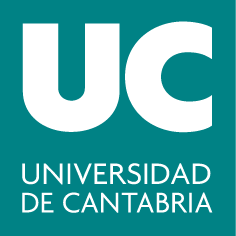

#### ***Grado en Ingeniería ****de los Recursos Energéticos / ****Grado en Ingeniería ****de los Recursos Mineros*

## **Álgebra Lineal y Geometría**

# **Práctica 2: Espacios Vectoriales**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Encontrar las relaciones de dependencia lineal en un conjunto de vectores.

- Hallar la base de un subespacio.

- Calcular la suma e intersección de subespacios, dados por sus ecuaciones implícitas o en forma paramétrica.

### Comandos útiles

- Para definir una matriz combinamos la definición de vectores fila y columna

M=[1 2 3; 4 5 6] % matriz de 2 filas y 3 columnas 

M =      1     2     3
     4     5     6


- `rref(A)`: Halla la forma escalonada reducida (y los pivotes) de una matriz A. También puede proporcionar las posiciones de las columnas pivotales. Ejemplos:

[redM, pivM] = rref(M)

redM =      1     0    -1
     0     1     2


pivM =      1     2


Hay dos resultados: la forma escalonada reducida y las posiciones de las columnas pivotales.

- `null(A, 'r'): `Devuelve la solución al sistema de ecuaciones homogéneo de matriz de coeficientes `A`. El argumento `'r'` es opcional. Lo usaremos habitualmente, pues da lugar a soluciones compuestas por números racionales (que se pueden expresar como una fracción), que resultan más manejables. Lógicamente, las soluciones devueltas con y sin `'r'` son igual de válidas. Ver la práctica 1 para la interpretación del resultado de `null`.

H=null(M, 'r')

H =      1
    -2
     1


- `format`: Cambia el formato de los resultados.

format rat % Para tener el resultado en formato de cociente (ratio)
format long % Para recuperar el formato decimal con 15 decimales
format short % Para recuperar el formato decimal con 4 decimales

### Ejercicios resueltos

*Nota: las lineas de código que terminan en *`;`* no muestran resultado por pantalla, mientras que la mayoría sí lo muestran, para facilitar vuestra comprobación.*

#### **Ejercicio 1: Relaciones de dependencia lineal**

Comprobar si el siguiente conjunto de vectores de $\mathbb{R}^{5}$  forma un sistema libre o ligado, y en el ese caso hallar una relación de dependencia.


$$A= \lbrace(-2, 4, 0, -1, 2), (2, 1, 2, -1, 1), (1,0,2,1,0), (0,1,-2,-3,1)\rbrace$$


Introducir los vectores y formar una matriz con ellos, colocados por columnas

a=[-2, 4, 0, -1, 2]';
b=[2, 1, 2, -1, 1]';
c=[1,0,2,1,0]';
d=[0,1,-2,-3,1]';
A=[a,b,c,d] 

A =     -2     2     1     0
     4     1     0     1
     0     2     2    -2
    -1    -1     1    -3
     2     1     0     1


Usamos la forma reducida de la matriz que forman los vectores para encontrar la dependencia:

[red, cp]=rref(A) 

red =      1     0     0     0
     0     1     0     1
     0     0     1    -2
     0     0     0     0
     0     0     0     0


cp =      1     2     3


vectoresLI= A(:, cp)

vectoresLI =     -2     2     1
     4     1     0
     0     2     2
    -1    -1     1
     2     1     0


Al haber solo 3 columnas pivotales de las 4 posibles, el sistema es ligado. La columna no pivotal (la 4ª) proporciona la dependencia $d=0a+1b-2c$, como se comprueba:

d-b+2*c % La comprobación ha de dar el vector nulo.

ans =      0
     0
     0
     0
     0


#### **Ejercicio 2: Base de un subespacio**

Hallar las ecuaciones paramétricas y una base del subespacio $S$ de $\mathbb{R}^ {4}$ definido por las ecuaciones implícitas: 


$$S \equiv \lbrace x-y+2z+3t=0; 3x-2y+z-t=0 \rbrace$$


En primer lugar, se escriben los coeficientes de cada ecuación en filas, ya que $A\vec{x}=\vec{0}$, donde $\vec{x}$ es el vector columna de incógnitas:

A = [1 -1 2 3; 3 -2 1 -1] % A es la matriz de coeficientes

A =      1    -1     2     3
     3    -2     1    -1


- Forma 1: usando la forma reducida de la matriz de coeficientes

[red, cp]=rref(A) 

red =      1     0    -3    -7
     0     1    -5   -10


cp =      1     2


De donde se obtiene que la forma paramétrica de parámetros a y b sería: x=3*a+7*b, y=5*a+10*b, z=a, t=b. De la forma paramétrica, deducimos que una base está formada por los vectores $(3,5,1,0), (7, 10,0,1)$.

- Forma 2: resolviendo directamente el sistema homogéneo:

H=null(A, 'r')

H =      3     7
     5    10
     1     0
     0     1


Cada columna de H es un vector de la base de S. Por lo tanto, las ecuaciones paramétricas, trabajando en simbólico, serían:

syms a b; a*H(:,1)+b*H(:,2) % son todas las C.L. de los vectores de la base

$$ans = \left(\begin{array}{c} 3\,a+7\,b\\ 5\,a+10\,b\\ a\\ b \end{array}\right)$$

#### **Ejercicio 3: Suma e intersección de subespacios**

Considerar en $\mathbb{R}^4$ los siguientes subespacios $S$ y $T$.


$$S=\lbrace(x,y,z,t) /x + 2y +z -t = 0;  z - t = 0\rbrace $$
        
$$ T= \lbrace(1,1,1,1)\rbrace$$


a) Obtener una base de $S+T$ y su dimensión.

b) Obtener una base de $S \cap T$y su dimensión.

c) Justificar si $S$ y $T$ están en suma directa.

d) Justificar si $S$ y $T$ son o no suplementarios.

a) Obtener una base de $S+T$ y su dimensión.

En primer lugar, hallamos una base de *𝑆*:

coefS=[1 2 1 -1; 0 0 1 -1]; % coeficientes de las implícitas en filas
baseS=null(coefS, 'r') 

baseS =     -2     0
     1     0
     0     1
     0     1


Se obtiene una base de S en columnas, por lo tanto, $dim(S)=2$.

Respecto a $T
$, ya nos dan una base así que expresamos el vector como vector columna:

baseT=[1 1 1 1]'

baseT =      1
     1
     1
     1


Dado que es un único vector, $dim(T)=1$.

Hallamos una base de la suma considerando conjuntamente los vectores que forman la base de $S$ y de $T$y analizando si esos vectores son linealmente independientes.

baseSuma=[baseS baseT] 

baseSuma =     -2     0     1
     1     0     1
     0     1     1
     0     1     1


rf=rref(baseSuma)

rf =      1     0     0
     0     1     0
     0     0     1
     0     0     0


Hemos comprobado que son 3 vectores linealmente independientes, por lo tanto, forman base de $S+T$, y $dim(S+T)=3$.

b) Obtener una base de $S \cap T$y su dimensión.

A continuación se obtiene una base de la intersección resolviendo el  sistema homogéneo que forman todas las ecuaciones implícitas de $S$ y $T$ juntas. Ya tenemos las ecuaciones implícitas de $S$ pero no las de $T$ (ver implicitación en los apuntes). Como estamos en $\mathbb{R}^4$ y $dim(T)=1$, $T$ tendrá 3 ecuaciones implícitas. Se pueden calcular a mano: $-x + y= 0, -x + z = 0, -x + t = 0$, o con MATLAB como se indica a continuación. Sabemos que cualquier vector de $T$(y en particular los vectores de la base) verificarán las ecuaciones implícitas del subespacio, cuya forma general será $Ax+By+Cz+Dt=0$. Por tanto, bastará con resolver el sistema homogéneo cuya matriz de coeficientes estará formada por los vectores de la base (colocados en filas), y en el que las incógnitas serán precisamente los coeficientes de las ecuaciones implícitas que buscamos $A, B, C, D$:

coefT= null(baseT','r')' % trasponemos baseT porque era un vector columna

coefT =     -1     1     0     0
    -1     0     1     0
    -1     0     0     1


Las filas dan directamente los coeficientes de las implícitas de $T$.

Una vez tenemos las ecuaciones implícitas de $S$ y de $T$, se calcula la base de la intersección resolviendo el sistema de las 5 ecuaciones juntas:

coefM=[coefS;coefT]

coefM =      1     2     1    -1
     0     0     1    -1
    -1     1     0     0
    -1     0     1     0
    -1     0     0     1


Resolviendo el sistema:

baseIntersec=null(coefM, 'r')


baseIntersec =

  4×0 empty double matrix



En este caso se obtiene que la intersección es cero.

c) ¿Están en suma directa? Sí, porque $dim(S+T)= dim(S) + dim(T)$, es decir, la dimensión de la intersección es cero.

d) ¿Son suplementarios? Aunque están en suma directa, la dimensión del subespacio suma es 3 y la dimensión del espacio total es 4 ($\mathbb{R}^4$), por lo tanto no son suplementarios.

### Ejercicios propuestos

Se propone resolver con MATLAB los ejercicios de las hojas de problemas del tema 3, en especial: **3.3, 3.5, 3.7, 3.8, 3.9**.